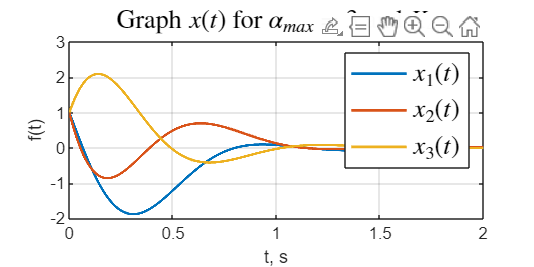

open_system('task_1_sim');
set_param('task_1_sim/x', 'VariableName', 'x')
set_param('task_1_sim/u', 'VariableName', 'u')
set_param('task_1_sim/u1', 'VariableName', 'u1')

out = sim('task_1_sim');

figure('Position', [100 100 800 400])
plot(out.x1,'-', 'LineWidth',1.5)

grid()
title('Graph $x(t)$ for $\alpha_{max} = 3$ and $K_4$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')

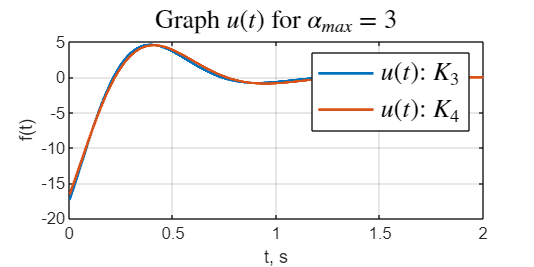

%xlim([0 2.2])



plot(out.u, 'LineWidth', 1.5)
hold on
plot(out.u1, 'LineWidth', 1.5)

grid("on")
title('Graph $u(t)$ for $\alpha_{max} = 3$', 'Interpreter','latex',  'FontSize', 14)
legend('$u(t)$: $K_3$', '$u(t)$: $K_4$','Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
%xlim([0 5.5])
hold off